# Setup

%% Default Parameters
dt = 0.02; 
tmax = 10000;
t = 0:dt:tmax;    

## k-nearest neighbours adjacency matrix

Let $K_{i}$ denote the set of the k-nearest neighbours of $x_{i}$

We assume that the adjacency matrix is of the form:


$$$$
a_{i,j}=
\begin{cases}
1, & \text{if } \quad x_{j} \in K_{i} \\
0, & \text{if } \quad x_{j} \notin K_{i}
\end{cases}
\quad \text{for } \quad i, j = 1, \dots, N
$$$$


That is, agents only interact with their k-nearest neighbours. Note that the adjacency matrix is **not** necessarily symmetric.

## Test

As a test, I set k = N. This should give the same results as the original model.

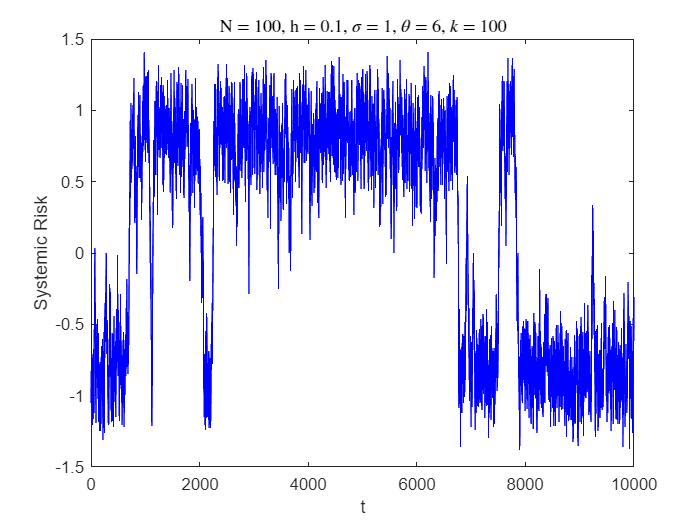

N = 100;
h = 0.1;                     
theta = 6;
sig = 1;
k = N;

x = SolveHomogeneousSDE(t, N, h, sig, theta, k);
plotknn(t, x, N, h, sig, theta, k);

### Varying $\sigma$

Simulations for different $\sigma$ = 1, 2, 4

In the original model, the system had two stable equilibria when σ was below the critical value (approximately $1$ for small $h$).

Fix $N, h, \theta, A$:

tmax = 10000;
t = 0:dt:tmax; 
N = 100;
h = 0.1;                     
theta = 6;
k_low = 40;
k_high = 50;

$\sigma = 1$:

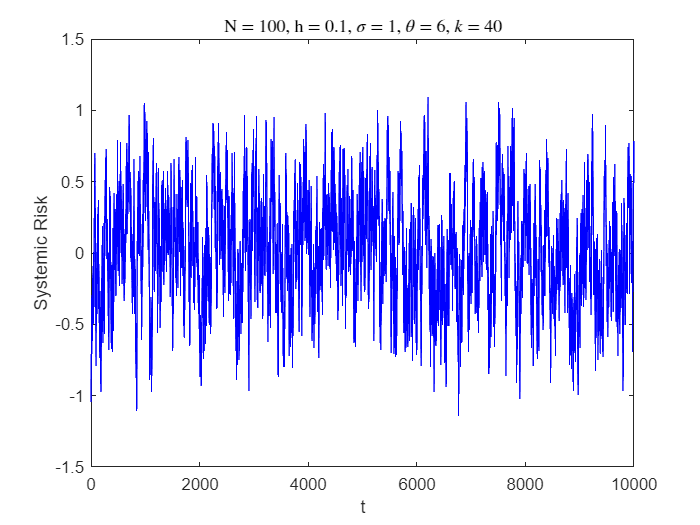

sig = 1;
x = SolveHomogeneousSDE(t, N, h, sig, theta, k_low);
plotknn(t, x, N, h, sig, theta, k_low);

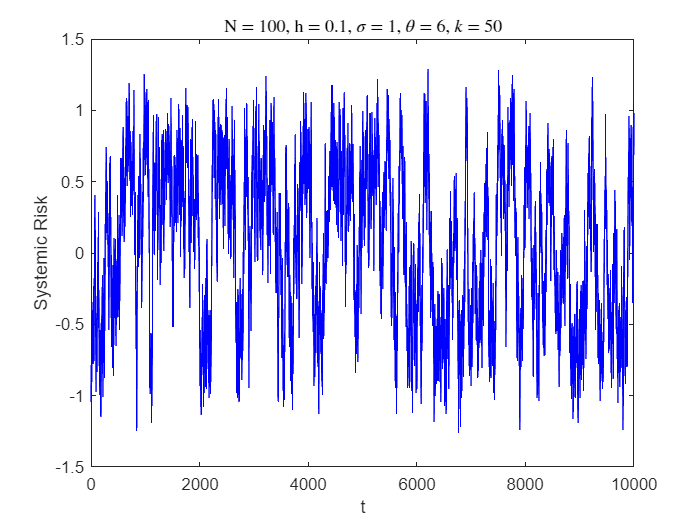

x = SolveHomogeneousSDE(t, N, h, sig, theta, k_high);
plotknn(t, x, N, h, sig, theta, k_high);

Conclusion: 

Sparsity in interactions makes the system less stable. If the number of interactions is too low, then the model moves from two equilibria to one.

compute_f(x) = $\frac{1}{N} \sum_{i = 1}^{N} a_{i,j}\left(x_{i}(t) - x_{j}(t)\right)$

function fvalues = compute_f(x, k)

    % Adjacency matrix for the k-nearest neighbours
    N = length(x);
    % Get indices of k-nearest neighbours of x
    idx = knnsearch(x, x, 'K', k);
    % Initialise adjacency matrix
    A = zeros(N, N);
    
    % A takes the value 1 for its k-nearest neighbours
    for i = 1:N
        A(i, idx(i, :)) = 1;
    end

    % Computes f(x) given an adjacency matrix A
    fvalues = zeros(N, 1);
    % Compute f(x_{j}) for j = 1,...,N
    for j = 1:N
        fvalues(j) = 1/N .* A(j, :) * (x - x(j));            
    end

end


$$f(t, x) = -h U\left(x_{j}(t)\right) + \theta \left( \frac{1}{N} \sum_{i = 1}^{N} a_{i,j}\left(x_{i}(t) - x_{j}(t)\right) \right)$$


function x = SolveHomogeneousSDE(t, N, h, sig, theta, k)
    
    % Define SDE
    x0 = -1 + zeros(N, 1);
    U = @(y) y.^3 - y;
    f = @(t, x) -h.*U(x) + theta.* compute_f(x, k);
    g = @(t, x) sig;    
   
    % Use Euler-Maruyama to solve SDE
    opts = sdeset('RandSeed', 1);
    x = sde_euler(f, g, t, x0, opts); 
end

Plot KNN

function plotknn(t, x, N, h, sig, theta, k)

    xbar = mean(x, 2);
    figure; 
    plot(t, xbar, 'b');
    title(['N = ' num2str(N) ',' ...
        ' h = ' num2str(h) ',' ...
        ' $\sigma$ = ' num2str(sig) ',' ...
        ' $\theta$ = ' num2str(theta(:).') ',' ...
        ' $k$ = ' num2str(k)], ...
    "Interpreter", "latex");
    xlabel('t'); ylabel('Systemic Risk');

end